figure
imagesc(eccentricityMap(:,:,1));
title({'Myosin Light Chain 9 Eccentricity Map ';'210108-2-3-R205-L-64x4-5x1-t100r64o64v5'});
colorbar; axis image
xlabel('Coordinates in x'); ylabel('Coordinates in y');
xt = xticks; xtls = (xt*opt.ROIshift*opt.pixelSize); xticklabels = {xtls};
yt = yticks; yticklabels = (yt*opt.ROIshift*opt.pixelSize);
xlabel('Distance (\mum)'); ylabel('Distance (\mum)');

figure;
vectorFrame = 6

vectorFrame = 6

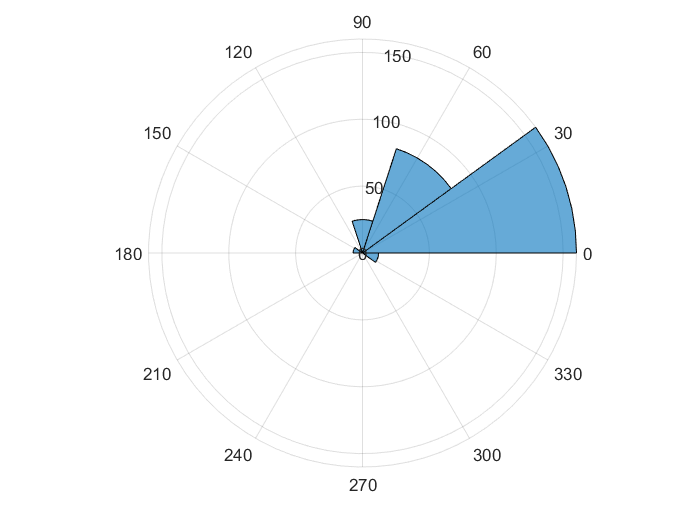

polarhistogram(deg2rad(Omega(:,:,vectorFrame)));

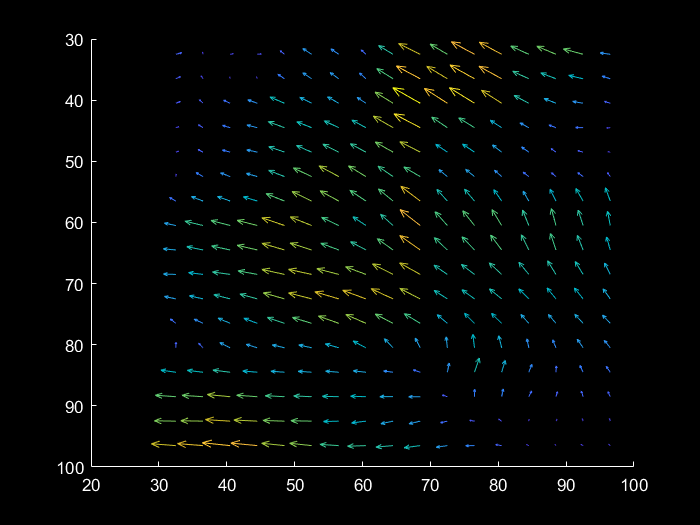

figure;
quiverc(position_y, position_x, -Vx(:,:,vectorFrame), -Vy(:,:,vectorFrame), 1); axis ij; 

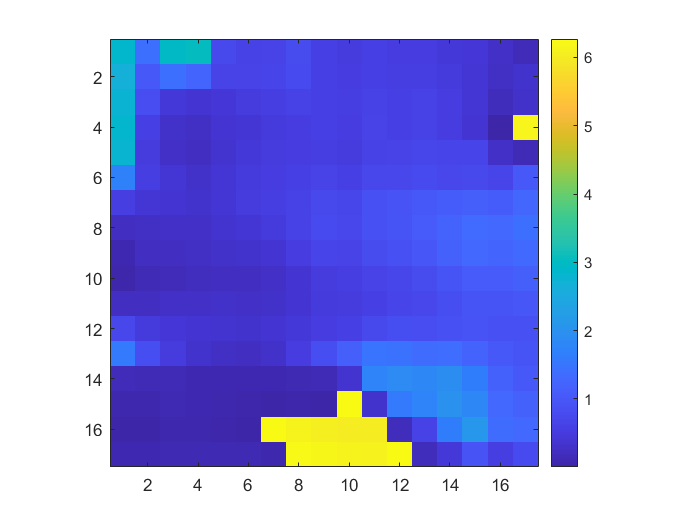

% c = colorbar; c.Color = 'w';
figure;
imagesc(deg2rad(Omega(:,:,vectorFrame))); colormap hsv; axis image; colorbar;

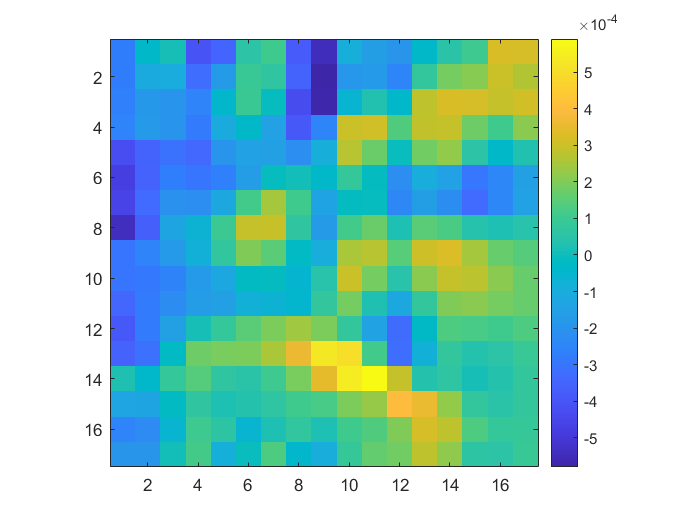

div = divergence(position_y, position_x, -Vx(:,:,vectorFrame), -Vy(:,:,vectorFrame));
figure;imagesc(div); axis image; colorbar

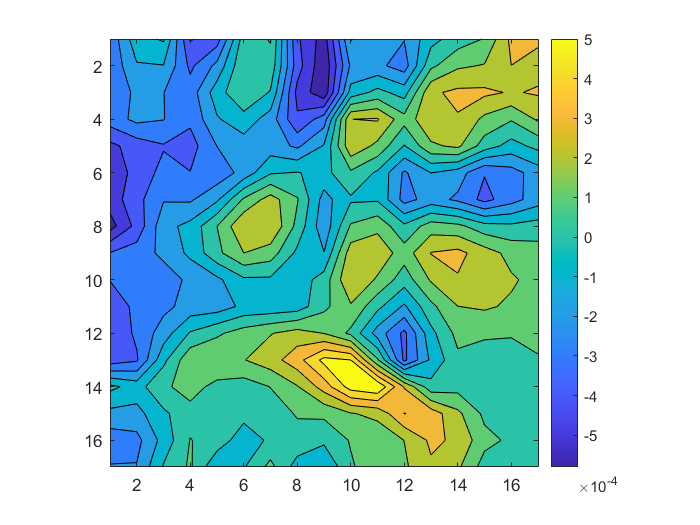

figure; contourf(div);axis ij equal; colorbar;

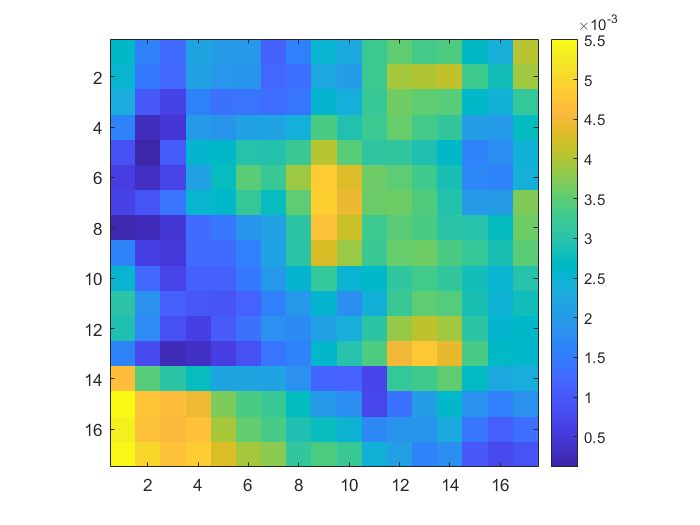

imagesc(VelMap(:,:,vectorFrame)); colorbar; axis image;

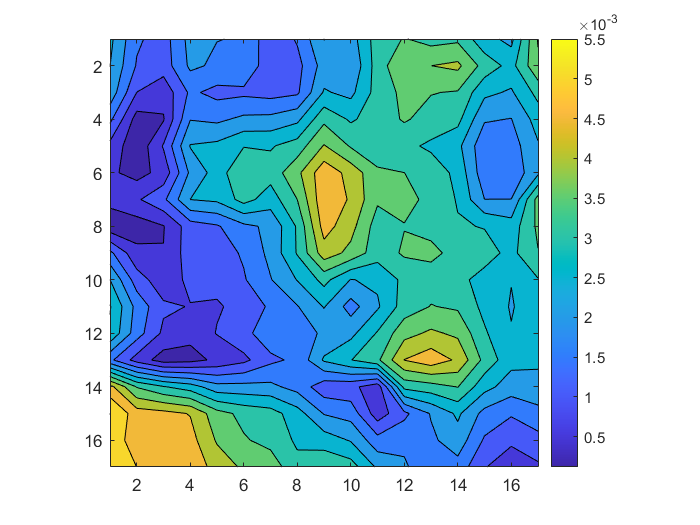

contourf(VelMap(:,:,vectorFrame));axis ij equal; colorbar;